# BME3053C Final Project

Author: William Bowers, Jackson Haynes, Taylor Kissane, Audrey Singletary

Course: BME 3053C Computer Applications for BME

Term: Spring 2024

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: jackson.haynes@ufl.edu, singletarya@ufl.edu, t.kissane@ufl.edu, william.bowers@medicine.ufl.edu

April 20th, 2024

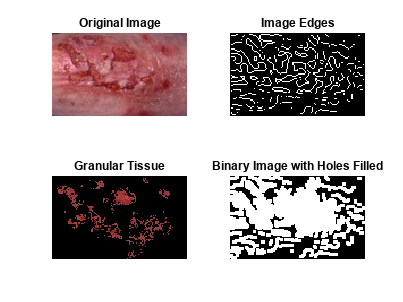

clc; clear; close all;

% Read the image Convert to grayscale
image = imread('leg-ulcers-0024.jpg');
subplot(2,2,1) 
imshow(image) 
title('Original Image');

% Convert to grayscale
I = rgb2gray(image);

% Apply the log edge detection
[~, thresh] = edge(I, "log");

% Set fudge factor
fudgeFactor = 0.7;

% Detect the edges
Iedge = edge(I, "log", fudgeFactor*thresh);
subplot(2,2,2)
imshow(Iedge)
title('Image Edges')

% Dilate the images first by creating two linear structuring elements se90 and se0 whose length are 3, and angles are 90 degrees and 0 degrees
se90 = strel('line',3,90);
se0 = strel('line',3,0);
Idilate = imdilate(Iedge,[se90 se0]);

% Fill in the holes
Ifill = imfill(Idilate, "holes");
subplot(2,2,4)
imshow(Ifill)
title('Binary Image with Holes Filled')

% Calculate size of wound by counting number of logical pixels
wound_size = length(find(Ifill == 1));

% Create Red and Blue color channels
red_channel = image(:,:,1);
blue_channel = image(:,:,3);

% Define thresholds for skin color in the 'a' and 'b' channels
red_threshold = [140 255];
blue_threshold = [0 70];

% Create a binary mask for skin regions based on color thresholds
gran_mask = (red_channel >= red_threshold(1) & red_channel <= red_threshold(2)) & ...
            (blue_channel >= blue_threshold(1) & blue_channel <= blue_threshold(2));

% Apply the mask to the original image to extract regions of granulation
gran = bsxfun(@times, image, cast(gran_mask, 'like', image));

% Display the results
subplot(2,2,3) 
imshow(gran)
title('Granular Tissue');


% Calculate number of thresholded pixels by creating grayscale image
gray = rgb2gray(gran);
gran_size = bwarea(gray);

% Calculate percent granulation
gran_per = gran_size/wound_size;
display(gran_per)

gran_per = 0.1920